# Terahertz band in Body-communication Simulator 

## Description

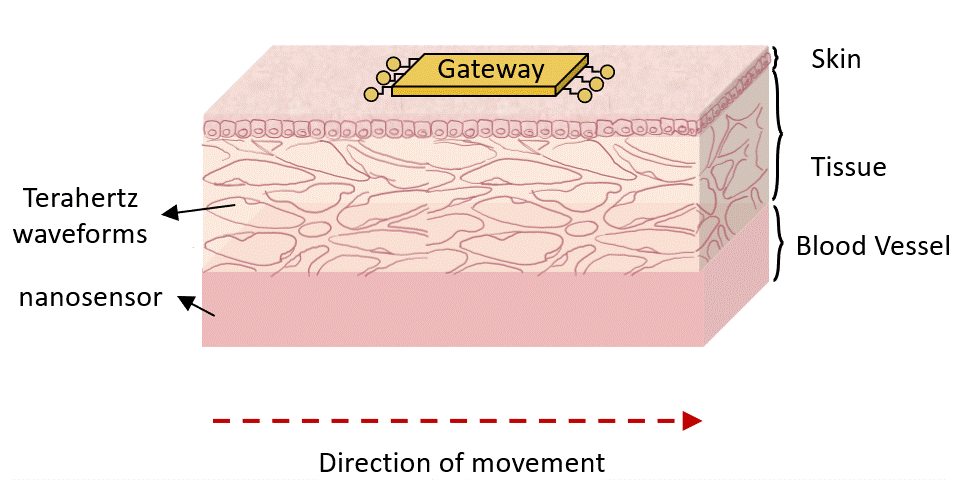

Figure 1: System model.

This code aims to simulate the communication performance between traveling nanosensors in the blood flow and external wearables, as depicted in Fig. 1. The communication is produced in the terahertz band. It takes into account the impact of mobility as the Doppler effect. The modulation format is the binary phase shift keying (BPSK). 

#### Communication Channel Model

The communication channel between the nanosensor and the Gateway is modeled according to the equation [1]:

$r(t)=g_d\,s(t-\tau_d)\,e^{j2\pi\nu t}$, (1)

where $g_d$ is the channel gain, $\tau_d$ is the propagation delay, and $\nu$ is the Doppler frequency as:

$\nu=v\cos(\phi)\frac{f_c}{c_0}$. (2)

In Eq. (2) $v$ is the velocity of the nanosensor, $c_0$ is the propagation speed of the waveform (speed of light), $f_c$ is the carrier frequency, and $\phi$ is the angle of arrival of the wave relative to the direction of motion of the nanosensor, as depicted in Fig. 2.

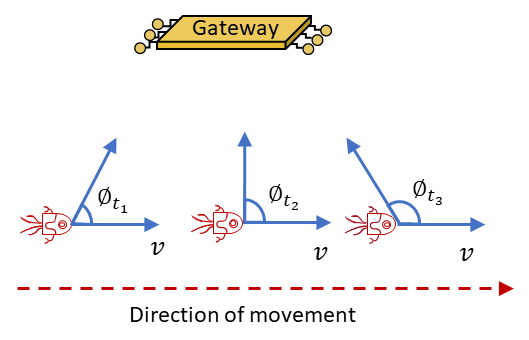

Figure 2: Description of the angle of emissions from the nanosensors along the vessel.

This interface provides adjustable parameters regarding the center frequency for communications, and distance parameters such as the tissue and vessel thickness, as well as the communication range given by the distance between the nanosensor and the Gateway, see Fig. 3. The communication range is always between the minimum and maximum distance lengths.

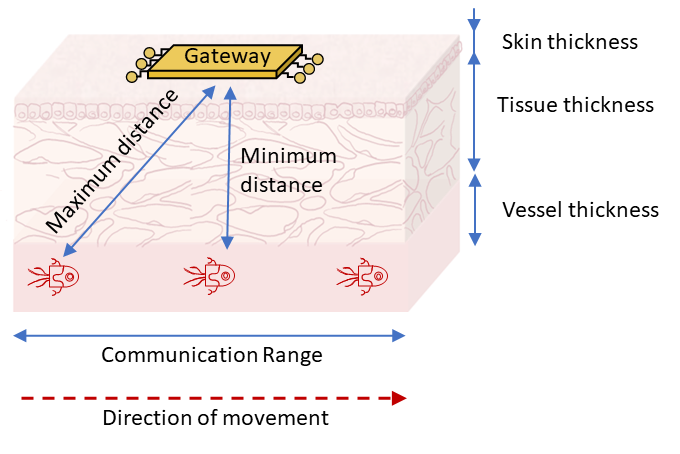

Figure 3: Representation of distances in the tissue.

The communication is modeled in baseband. Constellation points are produced according to the selected waveform (BPSK in this case). The received constellation points are computed after multiplying their amplitude by the channel gain (inverse of the path loss), and rotating the constellation points according to the doppler term (see Eq. (2)) and the transmission delay (negligible for the wireless communication in the milli-meter distance).

#### **Mobility model**

The animation in Fig. 4 illustrates the nanosensor's movement along the vessel. The nanosensor moves from left to right following a straight trajectory. The speed of the nanosensor follows the blood speed defined in the Parameters section of this code. 

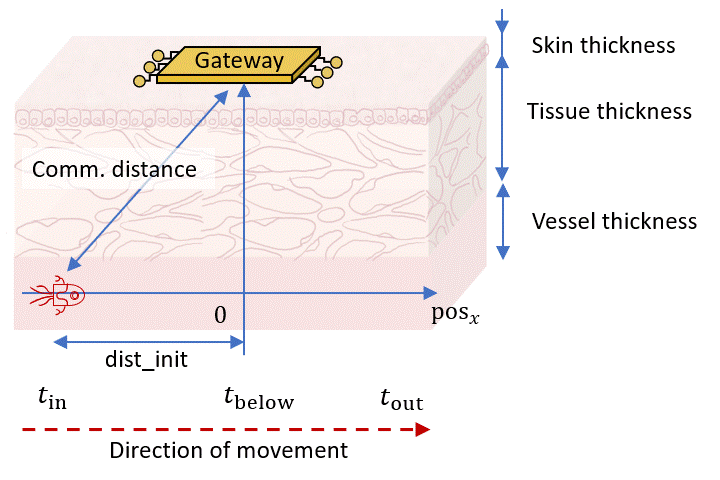

Figure 4: Reference system to evaluate the movement of the nanosensor.

#### Outputs

Outputs are provided regarding the communication scheme as:

- The channel gain versus time: $g_d$ in (1). This is evaluated using the reference in [2].

- The Doppler frequency: $\nu$ according to (2).

- Emmited constellation points.

- Received constellation points

- The achievable bit error rate (BER) versus time.

#### How to run this code

This code runs directly when clicking the run button or updating the parameters below. This code calls to functions implemented in C/C++ (see terahertz.c and terahertz.h). The functions defined in these two files simulate and evaluate the communication system. To re-build these functions, it is needed to install the [MinGW-w64 Compiler (free)](https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html) and to uncomment lines in the compiling block below.

## Parameters

#### **Physiological  Parameters**

**Tissue and Vessel Thickness in meters, see Fig. 3: **

Skin_thickness =76*10^(-6); %Epidermis, further details in [4]
Tissue_thickness=1000*10^(-6);%Dermis, further details in [5]
Vessel_thickness= 200*10^(-6);%Vessel, further details in [6]


**Blood speed (m/s):**

blood_speed_max=0.3*10^(-1); %Blood speed in the vessel center according to [7] (aorta: 0.2 m/s, arteries: 0.1 m/s, veins: 0.03 m/s)

#### **Waveform parameters**

**Communication range (meters)**

The initial position of the nanosensor refers to the x-direction in the bottom edge of the vessel. It is evaluated with the `dist_init_x` value from the control below, see Fig. 4. Based on the initial position value, the initial communication distance with the Gateway is derived using the Pythagoras theorem.

L_comm=1000*10^(-6);%distance to the position below the gateway, see Fig. 4 above
d_max=1.3*10^(-3);

**Waveform Parameters**

mod_order="Gaussian";
P_Tx_Watts=4*10^3;%typical values are given in [3]
Freq_Hz=0.14*10^12;
pulse_rate=1*10^6;%transmission bit rate in the units of Giga bit per second
pulses_period=10^3; %total of pulses in zero between two pulses

**Sampling**

sampling_time=1/pulse_rate*2*10^(-1);
L=floor(1/pulse_rate/sampling_time);%total of samples per pulse

**Channel**

%computing level of noise
%N_0=4.28*10^(-21);

c = 299792458.0; %speed of light in vacuum
kB = 1.38064852e-23; %Boltzman constant
t0 = 310; %reference temperature
k = 0.0072; %extinction coefficient from blood absoprtion coefficient

Tmol = t0 * (1- exp((-4*pi*Freq_Hz*(Skin_thickness+Tissue_thickness+Vessel_thickness)*k)/c));  
N_mol = kB*Tmol*pulse_rate;
disp(['Molecular Noise Power: ',num2str(10*log10(N_mol)),' dB'])

Molecular Noise Power: -156.4851 dB


**Receiver**

sensitivity_WpHz=10^(-10);% receptor sensitivity in watts per sqrt(hertz)
sensitivity_dBW=10*log10(sensitivity_WpHz*sqrt(pulse_rate));
%evaluating the noise power
wstop=1/(pulses_period*L)/2/sampling_time;
var_AWGN=sensitivity_WpHz*sqrt(wstop);
% var_AWGN=sensitivity_WpHz*sqrt(pulse_rate);

disp(['WGN Noise Power: ',num2str(10*log10(var_AWGN)),' dB'])

WGN Noise Power: -86.5051 dB


**Plotting**

fontsize=20;%Font size for the plots

**Simulator**

total_vessel_streams=10^2;%total of vessel streams
total_dist=10^2;%total of distances
total_power=10^2;%total of power levels
vessel_per=[0.06 0.2];%percentage of the vessel thickness

## **Compiling the functions in C code**

Uncomment the next lines in this code block when

- Editing the terahertz.c or terahertz.h files or 

- Updating the total of bits to transmitt with the variable above "total_bits" or 

- Updating the bit rate "bit_rate_bps"

% %% choosing the C++ compiler, if not previously installed at the local PC, follow steps to install MinGW-w64 Compiler in Matlab (free) https://www.mathworks.com/help/matlab/matlab_external/install-mingw-support-package.html.
% %% mex -setup C++ 
% %% compiling the C code for the path loss
% codegen -config:lib pathLoss_interface -args {0,0,0,0,0}
% codegen -config:mex pathLoss_interface codegen\lib\pathLoss_interface\pathLoss_interface.lib -args {0,0,0,0,0}

#### Evaluating the received power with the vessel stream and the nanosensor's position

P_Rx_max_dB=-35+10*log10(P_Tx_Watts);
P_Rx_min_dB=-80+10*log10(P_Tx_Watts);
pos_x_nanosensor=linspace(-L_comm,L_comm,total_dist);

l_v=linspace(vessel_per(1)*Vessel_thickness,vessel_per(2)*Vessel_thickness,total_vessel_streams);

pathLoss_dist_dB=zeros(total_vessel_streams,total_dist);
P_Rx_dB=zeros(total_vessel_streams,total_dist);
ncx2_CDF=zeros(total_power,total_vessel_streams,total_dist);

for pos_x=1:total_dist
%     pos_x/total_dist*100
    comm_dist_lv=sqrt(pos_x_nanosensor(pos_x).^2+(Skin_thickness+Tissue_thickness+l_v).^2);
    
    for dist_l_v=1:total_vessel_streams
        %evaluating the pathloss
        %calling to the pre-compiled C function
        pathLoss_dist_dB(dist_l_v,pos_x)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_lv(dist_l_v),Skin_thickness,Tissue_thickness,l_v(dist_l_v));
        P_Rx_dB(dist_l_v,pos_x)=10*log10(P_Tx_Watts)-pathLoss_dist_dB(dist_l_v,pos_x);
    end

end


**Plotting the received power with variable vessel stream**

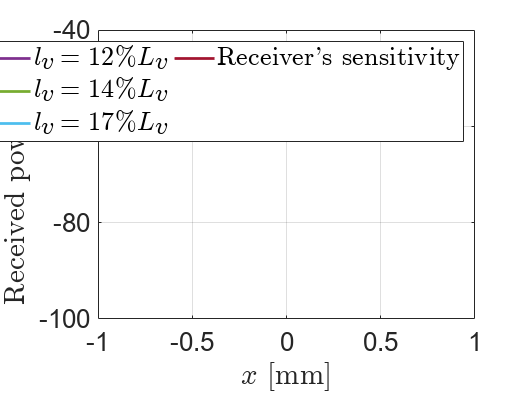

figure;
total_curves=6;
steps=15;
for i_l_v=1:steps:total_vessel_streams%1:floor(total_vessel_streams/total_curves):total_vessel_streams
    plot(pos_x_nanosensor*10^3,P_Rx_dB(i_l_v,:),'LineWidth',2); hold on;
end
%plotting the sensitivity of the receptor
plot(pos_x_nanosensor*10^3,sensitivity_dBW*ones(1,total_dist),'--','LineWidth',2);

legend_text=cell(1,total_curves+1);
i_l_v=1:steps:total_vessel_streams;
for m=1:total_curves
%   legend_text{m}=strcat('$l_v=',num2str(l_v((m*floor(total_vessel_streams/total_curves)))/Vessel_thickness*100,2),' \% L_v$');
  legend_text{m}=strcat('$l_v=',num2str(l_v(i_l_v(m))/Vessel_thickness*100,2),' \% L_v$');
end
legend_text{end}='Receiver''s sensitivity';

legend({legend_text{:}},...
    'Location','north','NumColumns',3,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html

xlabel('$x$ [mm]','Interpreter','latex');
ylabel('Received power [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);
grid on;

**Plotting the received power with the time perspective**

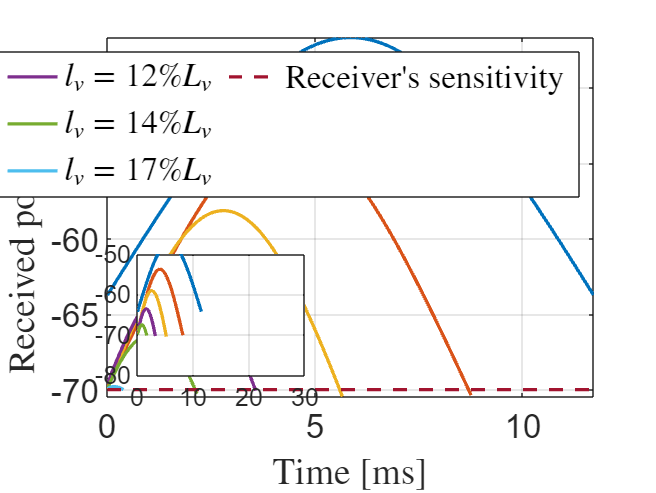

%pre-allocating space for the time window with the vessel stream
N_l_v=zeros(1,total_vessel_streams);%window length
w1_l_v=zeros(1,total_vessel_streams);%first sample window
w2_l_v=zeros(1,total_vessel_streams);%second sample window

figure;
total_plot=0;
end_point=0;
for i_l_v=1:steps:total_vessel_streams%i_l_v=1:steps:steps*total_curves%1:floor(total_vessel_streams/total_curves):total_vessel_streams
    k_1=find(P_Rx_dB(i_l_v,:)>=sensitivity_dBW,1);
    k_2=find(P_Rx_dB(i_l_v,k_1:end)<=sensitivity_dBW,1)-1;
    blood_speed=blood_speed_max/(Vessel_thickness)^2*(Vessel_thickness*l_v(i_l_v)-l_v(i_l_v).^2);
    if(isempty(k_1) && ~isempty(k_2))
        plot((0:total_dist-1)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,:),'LineWidth',2); hold on;
        total_plot=total_plot+1;
        end_point=k_2;
        N_l_v(i_l_v)=total_dist-(k_2+k1);
    elseif(isempty(k_2) && ~isempty(k_1))
        plot((0:total_dist-1)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,:),'LineWidth',2); hold on;
        total_plot=total_plot+1;
        w1_l_v(i_l_v)=k_1;
        w2_l_v(i_l_v)=total_dist;
        N_l_v(i_l_v)=total_dist-(k_1);
    elseif (~isempty(k_1) && ~isempty(k_2))
        plot((0:k_2)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,k_1:k_2+k_1),'LineWidth',2); hold on;
        total_plot=total_plot+1;
        end_point=k_2;
        w1_l_v(i_l_v)=k_1;
        w2_l_v(i_l_v)=k_2+k_1;
        N_l_v(i_l_v)=k_2;
    end
end

%plotting the sensitivity of the receptor
blood_speed=blood_speed_max/(Vessel_thickness)^2*(Vessel_thickness*l_v(1)-l_v(1).^2);
p=plot((0:total_dist-1)*sampling_time*10^3/blood_speed,sensitivity_dBW*ones(1,total_dist),'--','LineWidth',2);

legend_text=cell(1,total_plot+1);
i_l_v=1:steps:total_vessel_streams;
for m=1:total_plot
  legend_text{m}=strcat('$l_v=',num2str(l_v(i_l_v(m))/Vessel_thickness*100,2),' \% L_v$');
end
legend_text{end}='Receiver''s sensitivity';

legend({legend_text{:}},...
    'Location','north','NumColumns',3,'Interpreter',"latex",'FontSize',fontsize);% more properties on the legend at https://www.mathworks.com/help/matlab/ref/legend.html

xlabel('Time [ms]','Interpreter','latex');
ylabel('Received power [dB]','Interpreter','latex');
set(gca,'FontSize',fontsize);
grid on;

p = get(gca, 'Position');
h = axes('Parent', gcf, 'Position', [p(1)+.06 p(2)+.06 p(3)-.5 p(4)-.5]);
for i_l_v=2:floor(total_vessel_streams/total_curves):total_vessel_streams
    k_1=find(P_Rx_dB(i_l_v,:)>=sensitivity_dBW,1);
    k_2=find(P_Rx_dB(i_l_v,k_1:end)<=sensitivity_dBW,1)-1;
    blood_speed=blood_speed_max/(Vessel_thickness)^2*(Vessel_thickness*l_v(i_l_v)-l_v(i_l_v).^2);
    if(isempty(k_1) && ~isempty(k_2))
        plot(h,(0:total_dist-1)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,:),'LineWidth',2); hold on;
        total_plot=total_plot+1;
        end_point=k_2;
    elseif(isempty(k_2)&& ~isempty(k_1))
        plot(h,(0:total_dist-1)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,:),'LineWidth',2); hold on;
        total_plot=total_plot+1;
    elseif (~isempty(k_1) && ~isempty(k_2))
        plot(h,(0:k_2)*sampling_time*10^3/blood_speed,P_Rx_dB(i_l_v,k_1:k_2+k_1),'LineWidth',2); hold on;
        total_plot=total_plot+1;
        end_point=k_2;
    end
end
grid on;
set(gca,'FontSize',fontsize-5);
set(h, 'Xlim', [0 30], 'Ylim', [-80 -50]);

**Plotting the CRLB for the vessel stream**

${\textrm{CRLB}}_{l_v } =\frac{\sigma^2 }{\sum_{w_1 }^{w_2 } {\left(\frac{\partial }{\partial l_v }P_{\textrm{Rx}} \right)}^2 }$ [10, Sec. 3.5 pag. 35]

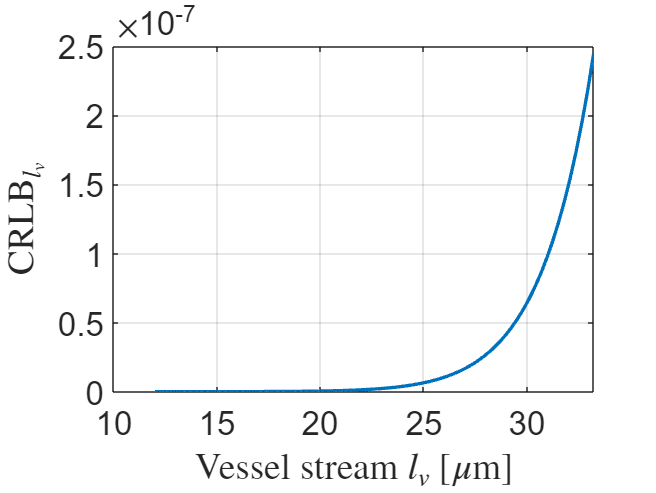

%finding the vessel stream where the maximum amplitude is less than the
%sensitivity
cond=true;
l_v_total=1;
while cond
    if(max(P_Rx_dB(l_v_total,:))<=sensitivity_dBW)
        cond=false;
    elseif l_v_total==total_vessel_streams
        cond=false;
    else
        l_v_total=l_v_total+1;
    end
end

%evaluating the differential
d_l_v=(l_v(end)-l_v(1))/total_vessel_streams;
%evaluating the first derivative with respect to the vessel stream
P_Rx_first_derivative_sum=sum(((10.^(P_Rx_dB(2:l_v_total,:)/10)-10.^(P_Rx_dB(1:l_v_total-1,:)/10))/d_l_v).^2,2);


figure;
plot(l_v(1:l_v_total-1)*10^6,var_AWGN./P_Rx_first_derivative_sum(1:l_v_total-1),'LineWidth',2); grid on;
xlabel('Vessel stream $l_v$ [$\mu$m]','Interpreter','latex');
ylabel('CRLB$_{l_v}$','Interpreter','latex');
grid on;
set(gca,'FontSize',fontsize);

**Plotting the STO with the **${\textrm{CRLB}}_{t_{\textrm{peak}} }$

$\begin{array}{l}
{\textrm{STO}}_{\min } =\sqrt{{\textrm{CRLB}}_{t_{\textrm{peak}} } }\\
{\textrm{CRLB}}_{t_{\textrm{peak}} } ={\left(\frac{\partial }{\partial l_v }t_{\textrm{peak}} \right)}^2 {\textrm{CRLB}}_{l_v } 
\end{array}$ [10, Eq. (3.14) pag. 36]

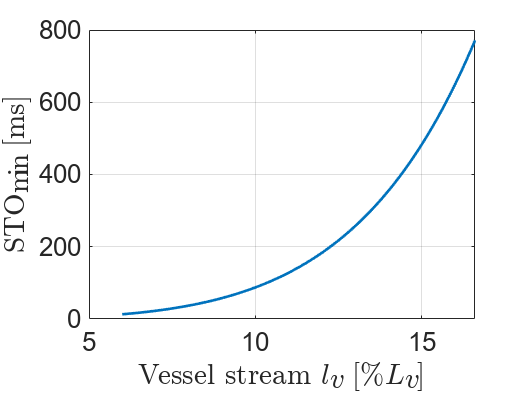

%evaluating the blood spead profile
blood_speed_profile=blood_speed_max/(Vessel_thickness)^2*(2*Vessel_thickness*l_v-l_v.^2);
%evaluating the derivate of the blood profile with respect to l_v
diff_blood_speed_profile=blood_speed_max/(Vessel_thickness)^2*(2*Vessel_thickness-2*l_v);
%evaluating the derivative of t_peak with respect to l_v
L_comm=sqrt(d_max^2-(Vessel_thickness+Tissue_thickness+l_v).^2);
d_t_peak_d_lv=-(2*(Vessel_thickness+Tissue_thickness+l_v))./(blood_speed_profile.*2.*L_comm)-L_comm./blood_speed_profile.^2.*diff_blood_speed_profile;

STO_CRLB=sqrt(var_AWGN*d_t_peak_d_lv(1:l_v_total-1)'.^2./P_Rx_first_derivative_sum(1:l_v_total-1));

figure;
plot(l_v(1:l_v_total-1)/Vessel_thickness*100,STO_CRLB*10^3,'LineWidth',2); grid on;
xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('STO$_{\mathrm{min}}$ [ms]','Interpreter','latex');
grid on;
set(gca,'FontSize',fontsize);

#### **Evaluating the BER**

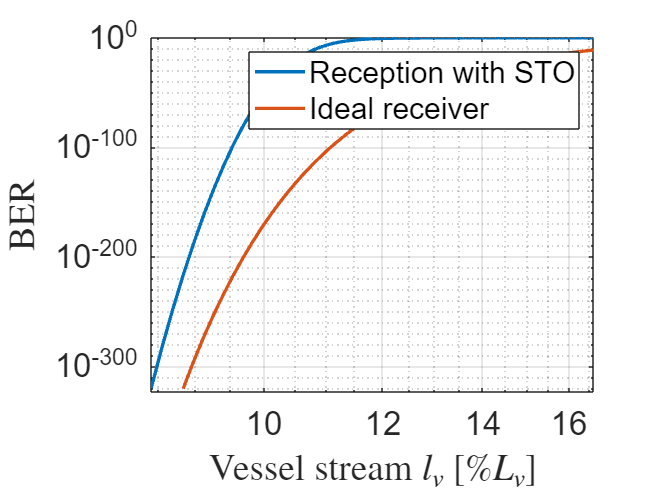

%evaluating the path loss produced by the sto
%position with time
pos_x_nanosensor_STO=blood_speed_profile(1:l_v_total-1).*STO_CRLB';
%communication distance with time
comm_dist_time_STO=sqrt(pos_x_nanosensor_STO.^2+(Skin_thickness+Tissue_thickness+l_v(1:l_v_total-1)).^2);

%evaluating the pathloss when performing ideal transmissions just below the
%Gateway
pos_x_nanosensor=0;
%communication distance with time
comm_dist_time=sqrt(pos_x_nanosensor.^2+(Skin_thickness+Tissue_thickness+l_v(1:l_v_total-1)).^2);


pathLoss_Gateway_dB_STO=zeros(1,l_v_total-1);
pathLoss_Gateway_dB=zeros(1,l_v_total-1);

for dist=1:l_v_total-1
    %calling to the pre-compiled C function
    pathLoss_Gateway_dB_STO(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time_STO(dist),Skin_thickness,Tissue_thickness,l_v(dist));
    pathLoss_Gateway_dB(dist)=2*pathLoss_interface_mex(Freq_Hz,comm_dist_time(dist),Skin_thickness,Tissue_thickness,l_v(dist));
end
SNR_dB_STO=10*log10(P_Tx_Watts)-pathLoss_Gateway_dB_STO-10*log10(var_AWGN);
SNR_dB=10*log10(P_Tx_Watts)-pathLoss_Gateway_dB-10*log10(var_AWGN);

figure;
loglog(l_v(1:l_v_total-1)*100/Vessel_thickness,qfunc(sqrt(10.^(SNR_dB_STO/10))),'LineWidth',2); grid on; hold on;
loglog(l_v(1:l_v_total-1)*100/Vessel_thickness,qfunc(sqrt(10.^(SNR_dB/10))),'LineWidth',2); 
xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('BER','Interpreter','latex');
legend('Reception with STO','Ideal receiver');
set(gca,'FontSize',fontsize);

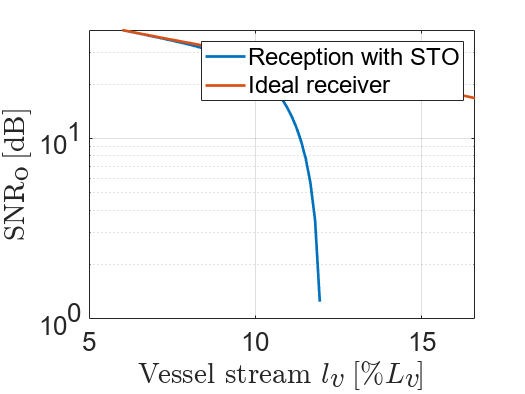


figure;
semilogy(l_v(1:l_v_total-1)*100/Vessel_thickness,SNR_dB_STO,'LineWidth',2); grid on; hold on;
semilogy(l_v(1:l_v_total-1)*100/Vessel_thickness,SNR_dB,'LineWidth',2);

xlabel('Vessel stream $l_v$ [$\%L_v$]','Interpreter','latex');
ylabel('SNR$_\mathrm{o}$ [dB]','Interpreter','latex');
legend('Reception with STO','Ideal receiver')
set(gca,'FontSize',fontsize);


% loglog(l_v(1:l_v_total-1),qfunc(sqrt(P_Tx_Watts.*10.^(-pathLoss_Gateway_dB/10)/var_AWGN)),'LineWidth',2);
% loglog(SNR_dB,qfunc(sqrt(SNR_dB.*10.^((pathLoss_Gateway_dB-pathLoss_sto_dB_th)/10))),'LineWidth',2);
% loglog(SNR_dB,qfunc(sqrt(SNR_dB)),'LineWidth',2);


% %nested plot
% p = get(gca, 'Position');
% h = axes('Parent', gcf, 'Position', [p(1)+.06 p(2)+.06 p(3)-.5 p(4)-.5]);
% x1=10;
% x2=15;
% loglog(h,SNR_dB(x1:x2),qfunc(sqrt(SNR_dB(10:15).*10.^((pathLoss_Gateway_dB-pathLoss_Gateway_dB_STO(x1:x2))/10))),'LineWidth',2); grid on; hold on;
% loglog(h,SNR_dB(x1:x2),qfunc(sqrt(SNR_dB(10:15).*10.^((pathLoss_Gateway_dB-pathLoss_sto_dB_th(x1:x2))/10))),'LineWidth',2);
% loglog(h,SNR_dB(x1:x2),qfunc(sqrt(SNR_dB(10:15))),'LineWidth',2);
% set(gca,'FontSize',fontsize-5);
% % set(h, 'Xlim', [-0.2 0], 'Ylim', [-5 -4]);

## **References**

[1] G. Matz and F. Hlawatsch, “Fundamentals of Time-Varying Communication Channels,” in Wireless Communications Over Rapidly Time-Varying Channels, F. Hlawatsch and G. Matz, Eds., Elsevier, 2011, pp. 1–63.

[2] J. Simonjan, B. D. Unluturk and I. F. Akyildiz, "In-Body Bionanosensor Localization for Anomaly Detection via Inertial Positioning and THz Backscattering Communication," in IEEE Transactions on NanoBioscience, vol. 21, no. 2, pp. 216-225, April 2022, doi: 10.1109/TNB.2021.3123972.

[3] J. M. Jornet and I. F. Akyildiz, "Channel Modeling and Capacity Analysis for Electromagnetic Wireless Nanonetworks in the Terahertz Band," in IEEE Transactions on Wireless Communications, vol. 10, no. 10, pp. 3211-3221, October 2011, doi: 10.1109/TWC.2011.081011.100545.

[4] G. Piro, P. Bia, G. Boggia, D. Caratelli, L.A. Grieco, L. Mescia, "Terahertz electromagnetic field propagation in human tissues: A study on communication capabilities," Nano Communication Networks, Volume 10, 2016, Pages 51-59, ISSN 1878-7789, [https://doi.org/10.1016/j.nancom.2016.07.010.](https://doi.org/10.1016/j.nancom.2016.07.010.)

[5] P. Oltulu, B. Ince, N. Kokbudak, F. Kılıc¸ ¨ et al., “Measurement of epidermis, dermis, and total skin thicknesses from six different body regions with a new ethical histometric technique,” Turk Plastik, Rekonstr ¨ uktif ve ¨ Estetik Cerrahi Dergisi (Turk J Plast Surg), vol. 26, no. 2, pp. 56–61, 2018. DOI: 10.4103/tjps.TJPS_2_17

[6] M. Fruchard, L. Arcese, and E. Courtial, “Estimation of the blood velocity for nanorobotics,” IEEE Transactions on Robotics, vol. 30, no. 1, pp. 93–102, 2013.

[7] A. C. Guyton and M. E. Hall, Guyton and Hall Textbook of Medical Physiology, 14th ed. Elsevier, 2015.

[8] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[9] J. M. Jornet and I. F. Akyildiz, “Femtosecond-Long Pulse-Based Modulation for Terahertz Band Communication in Nanonetworks,” IEEE Transactions on Communications, vol. 62, no. 5, pp. 1742–1754, May 2014

[10] S. Kay, Fundamentals of Statistical Signal Processing: Estimation Theory. Upper Saddle River, NJ: Prentice Hall, 1998